if ~exist('eyerecording', 'var')
    disp('loading compressed recording from file...')
    load('eyerecording.mat')
end

loading compressed recording from file...


eyerecording = activity(eyerecording, 50000)

eyerecording = struct with fields:
             ts: [1×85393694 double]
              x: [1×85393694 double]
              y: [1×85393694 double]
              p: [1×85393694 double]
     activityOn: [1×85393694 double]
    activityOff: [1×85393694 double]


skip = 1000;
scatter(eyerecording.ts(1:skip:end), eyerecording.activityOn(1:skip:end))

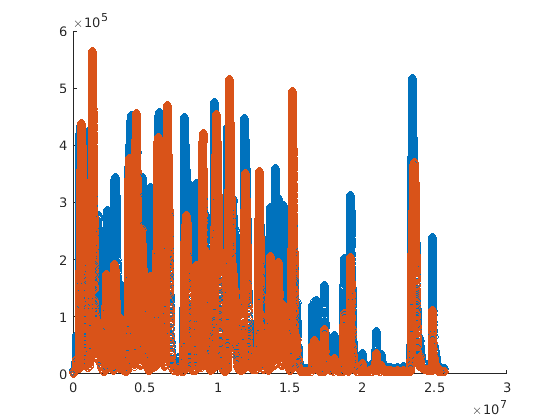

hold on
scatter(eyerecording.ts(1:skip:end), eyerecording.activityOff(1:skip:end))

collection = Collection('eyes');
subject = Subject('gregor', 0.88, collection);

created subject gregor


subject.addrecording(1, eyerecording, true);
subject.Recordings{1}.Center.Location = [320 240];
subject.Recordings{1}.Center.Times = [418900 1180000 6350000];
subject.BlinkLength = 250000;
subject.Recordings{1}.Dimensions = [640 480];
subject.Recordings{1}.GridSizes = [1 1];
subject.Modelblink = subject.Recordings{1}.getmodelblink(30);

Amplitude scale: 415099
